clear all
addpath('time');

## Periodic motion propagation

Initial conditions:

a=46000;
e=0.5;
n=sqrt(astroConstants(13)/(a^3));
teta_0=0;
dteta=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5);
init_conds=[0 dteta*(((1+e)^0.5)*((1-e)^1.5))/((-n)*(2+e)) dteta 0];

Run Simulink:

sim_out=sim('relative_dynamics.slx');

Plot

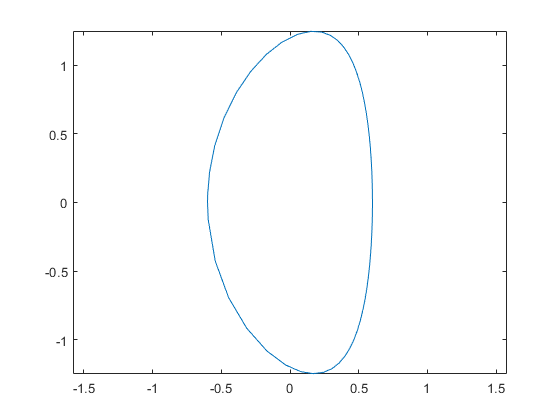

x=sim_out.simout.data(:,2);
y=sim_out.simout.data(:,4);
plot(x,y);
axis equal